% Initialize SAM model (this may take some time)
clear;close all;
sam = segmentAnythingModel;

img_path = 'Images/img_001.png';
boundaryPoints = segmentImageAndExtractBoundaries(img_path,sam);

% Fitting superellipses (n,a,b,angle,h,k)
superellipses = zeros(size(boundaryPoints,1),6);
for i = 1:size(superellipses, 1)
     x = EMS2D((boundaryPoints{i})','OutlierRatio',0);
     superellipses(i,1:2) = x(2:3);
     superellipses(i,3) = x(1);
     superellipses(i,4:5) = x(5:6);
     superellipses(i,6) = x(4);
end
Params = matrix_cell(superellipses);

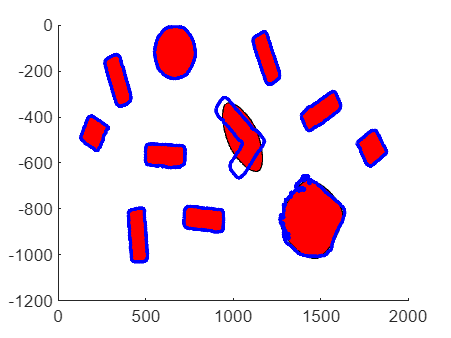

close all
plot_multiple_superellipses(Params)
hold on
% Loop through each boundary found and plot it
for k = 1:length(boundaryPoints)
    boundary = boundaryPoints{k}; % Get the k-th boundary
    plot(boundary(:,1), boundary(:,2), 'b', 'LineWidth', 2); % Overlay boundary on the image
end
hold off

Making the Voronoi diagram

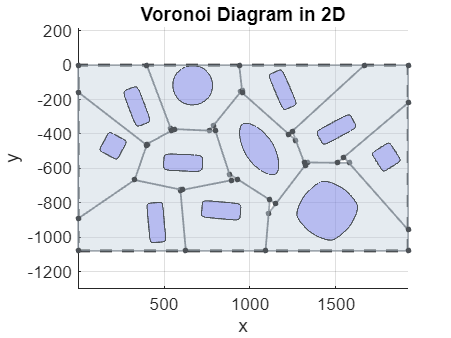

tic
img = imread(img_path);
[polyhedrons] = voronoi_diagram_2D(Params,img);

disp("Time Taken to make voronoi diagram : "+toc)

Time Taken to make voronoi diagram : 0.45555


Making the graph from diagram

Graph is fully connected.


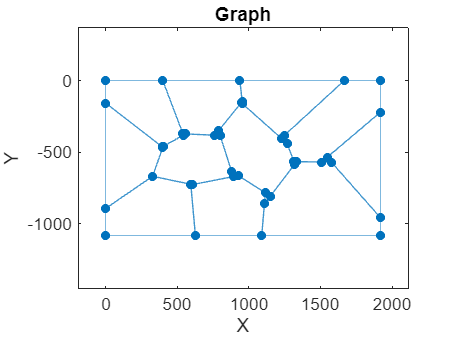

The graph is connected.


tic
vertexGraph = Copy_of_createVoronoiGraph(polyhedrons);

disp("Time Taken to make voronoi graph : "+toc)

Time Taken to make voronoi graph : 0.23447


Shortest path between any two points

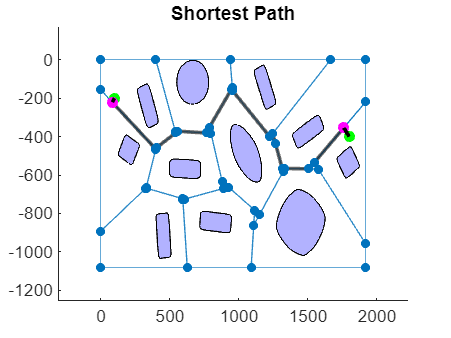

close all;
startPoint = [100,-200];endPoint = [1800,-400];
[updatedGraph,pathCoords] = ShortestPath(vertexGraph, startPoint, endPoint,Params);